**Homework Assignment 1**

SZF & EA, 2023

PQ. 1

clear all; close all; clc

Q1_Test = struct()

Q1_Test = struct with no fields.


test_data = struct()

test_data = struct with no fields.



A = eye(3);
myTest(:,:,1) = A;

B = elemRot('x',90);
myTest(:,:,2) = B;

C = elemRot('y',90);
myTest(:,:,3) = C;

D = elemRot('z',90);
myTest(:,:,4) = D;

E = B*C;
myTest(:,:,5) = E;

F = B*C*D;
myTest(:,:,6) = F;

% If more test cases are desired, add more here
% Index new test cases in accordance with others

for idx=1:length(myTest(1,1,:))
    Q1_Test(idx).AA = rot2AA(myTest(:,:,idx));
    Q1_Test(:,idx).Quat = rot2Quat(myTest(:,:,idx));
    Q1_Test(:,idx).ZYZ = rot2ZYZ(myTest(:,:,idx));
    Q1_Test(:,idx).ZYX = rot2ZYX(myTest(:,:,idx));
    
    % Generate data for testing question 2 functions with matlab functions
    % This is to provide valid quaternion and axis angle representation data points
    test_data(idx,:).Quat = rotm2quat(myTest(:,:,idx));
    test_data(idx,:).AA = rotm2axang(myTest(:,:,idx));

end

ans = 'The calculated sine of theta is zero. In this case, the angles rho and phi cannot be calculated and only their sum or difference may be specified.'

ans = 'The returned value is: [0;theta;sum of angles]'

ans = 'The calculated sine of theta is positive or negative one. In this case, the angles rho and phi cannot be calculated and only their sum or difference may be specified.'

ans = 'The returned value is: [0;theta;diff of angles]'

ans = 'The calculated sine of theta is zero. In this case, the angles rho and phi cannot be calculated and only their sum or difference may be specified.'

ans = 'The returned value is: [0;theta;sum of angles]'

ans = 'The calculated sine of theta is positive or negative one. In this case, the angles rho and phi cannot be calculated and only their sum or difference may be specified.'

ans = 'The returned value is: [0;theta;diff of angles]'

To access each of the test results, use the appropriate field name to access the desired element of the struct. For example, to access the axis angle representation of the second test case:

myAxis02 = Q1_Test(2).AA.Axis

myAxis02 =      1
     0
     0


myAngle02 = Q1_Test(2).AA.Angle

myAngle02 = 1.5708

PQ. 2

% Can use results from test above for input axis angle and quaternion matrices

Q2_Test = struct();

for idx = 1:length(myTest(1,1,:))
    Q2_Test(idx).QtoR = quaternian_to_rotation(test_data(idx,:).Quat');
    aa2r_data = test_data(idx,:).AA; 
    w = aa2r_data(1:3);
    theta = aa2r_data(4); 
    Q2_Test(idx).AAtoR = axisangle_to_rotation(w',theta);    

end

PQ. 3

q = [0,2,0];
s = [0,0,1];
h = 2;

Screw01 = Screw(q,s,h);

theta = pi;

T0 = [1 0 0 2;
      0 1 0 0;
      0 0 1 0;
      0 0 0 1];

T1 = zeros(4,4,4);

for a = 1:4
    T_Screw = Screw01.getScrewExp(a*theta/4);
    
    T1(:,:,a) = T_Screw*T0;
end

v =      2     0     2


v =      2     0     2


v =      2     0     2


v =      2     0     2



[S_o,phi] = screwMatLog(T1);
s_hat = S_o(1:3)

s_hat =          0
         0
    1.0000


h = S_o(1:3)'*S_o(4:6)

h = 2.0000

syms q1 q2 q3
q = [q1,q2,q3];
LHS = S_o(4:6)- h*s_hat;
RHS = cross(-s_hat,q);
eqs = [RHS(1) == LHS(1);RHS(2) == LHS(2);RHS(3) == LHS(3)];

% To find a solution for q, set q3 = 0
sol = solve(eqs(1:2),[q1;q2]);
q1 = double(sol.q1);
q2 = double(sol.q2);
q3 = 0;

q = [q1,q2,q3]

q =    -1.2997    4.7598         0


Plotting for PQ. 3

figure(1)
origin = T0; 

plot3( [0;5;0;0;0;0], [0;0;0;5;0;0], [0;0;0;0;0;5],'k'); hold on

plot3( [origin(1,4);origin(1,4)+origin(1,1)], [origin(2,4);origin(2,4)+origin(1,2)], [origin(3,4);origin(3,4)+origin(1,3)], 'r');
plot3( [origin(1,4);origin(1,4)+origin(2,1)], [origin(2,4);origin(2,4)+origin(2,2)], [origin(3,4);origin(3,4)+origin(2,3)], 'b')
plot3( [origin(1,4);origin(1,4)+origin(3,1)], [origin(2,4);origin(2,4)+origin(3,2)], [origin(3,4);origin(3,4)+origin(3,3)], 'g')

for idx = 1:length(T1(1,1,:))
    
    intermed_T = T1(:,:,idx)

    plot3( [intermed_T(1,4);intermed_T(1,4)+intermed_T(1,1)], [intermed_T(2,4);intermed_T(2,4)+intermed_T(1,2)], [intermed_T(3,4);intermed_T(3,4)+intermed_T(1,3)], 'r');
    plot3( [intermed_T(1,4);intermed_T(1,4)+intermed_T(2,1)], [intermed_T(2,4);intermed_T(2,4)+intermed_T(2,2)], [intermed_T(3,4);intermed_T(3,4)+intermed_T(2,3)], 'b')
    plot3( [intermed_T(1,4);intermed_T(1,4)+intermed_T(3,1)], [intermed_T(2,4);intermed_T(2,4)+intermed_T(3,2)], [intermed_T(3,4);intermed_T(3,4)+intermed_T(3,3)], 'g')
end

intermed_T =     0.7071   -0.7071         0    2.9850
    0.7071    0.7071         0    2.3132
         0         0    1.0000    1.5708
         0         0         0    1.0000


intermed_T =     0.0000   -1.0000         0    3.1416
    1.0000    0.0000         0    6.2832
         0         0    1.0000    3.1416
         0         0         0    1.0000


intermed_T =    -0.7071   -0.7071         0    3.2982
    0.7071   -0.7071         0   11.4248
         0         0    1.0000    4.7124
         0         0         0    1.0000


intermed_T =    -1.0000   -0.0000         0    4.2832
    0.0000   -1.0000         0   16.5664
         0         0    1.0000    6.2832
         0         0         0    1.0000


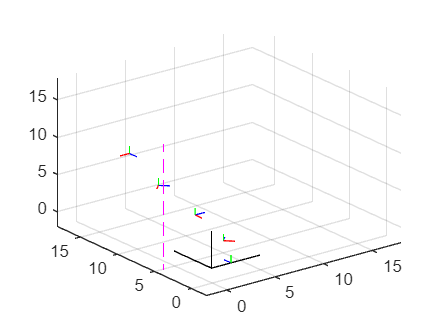


plot3([q1;q1],[q2,q2],[-3,15],'m--')

grid on
axis([-2 18    -2 18    -2 18])